# Blink to SOS

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

Visual signals, like blinking LEDs, remain relevant today because they provide immediate and easily understandable information. These signals effectively convey device status, error alerts, and critical information. Their simplicity and universal understanding make them indispensable in various industries, ensuring safety and enhancing communication.

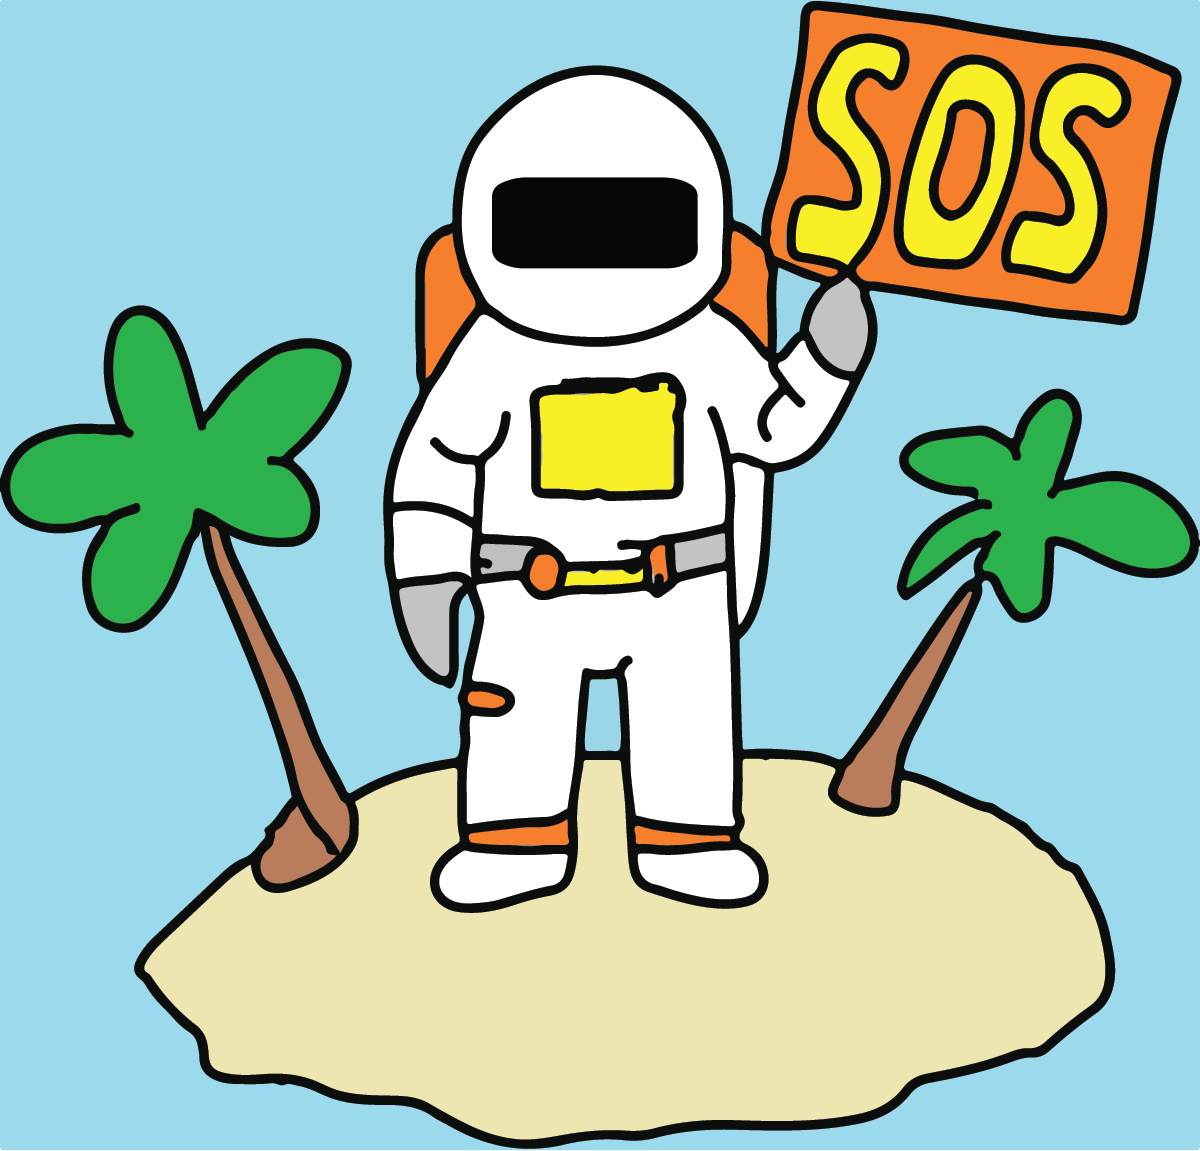

**Before you get started**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction 

### Set your hardware

This script is meant to be a first introduction to controlling Arduino Hardware with MATLAB and Simulink. You will also learn about analog and digital signals and how the hardware uses them. To follow the instructions in this script, you will need some standard hardware, including:

- An [Arduino board](https://www.arduino.cc/) supported by MATLAB & Simulink. The list of supported hardware is available in [SupportArduino.mlx](matlab:open('./SupportArduino.mlx')).

- An electronic breadboard.

- Some standard electronic components: LED, resistor, photoresistor, USB wire, jumper wire, etc.

If you have all the hardware listed above, you should be able to follow the rest of the scripts (and most of this module). You can now connect your Arduino to your computer. 

  **Try. **Connect your Arduino Board to this computer and select 

myBoard = "Arduino Uno";
if myBoard == "Other"
    error("The list includes all the board that are supported by the support packages."+...
        " If your board is not in this list, you will not be able to control it "+...
        "with MATLAB and Simulink.")
else
    wrappedDisp("Great! This hardware is compatible.")
end

To control the hardware with MATLAB & Simulink, you will need to install the two support packages:

- MATLAB Support Package for Arduino Hardware

- Simulink Support Package for Arduino Hardware

These support packages are a collection of MATLAB functions and Simulink blocks that can be used directly to control your hardware.

  **Try. **Not sure if these packages are installed? Click the following button to check your hardware and support packages installed.

 hardwareTest(myBoard);

### Board Overview

Arduino boards are open-source programmable microcontroller boards designed for the rapid prototyping of electronic devices. The boards themselves come with multiple pins, allowing the input and output of information.

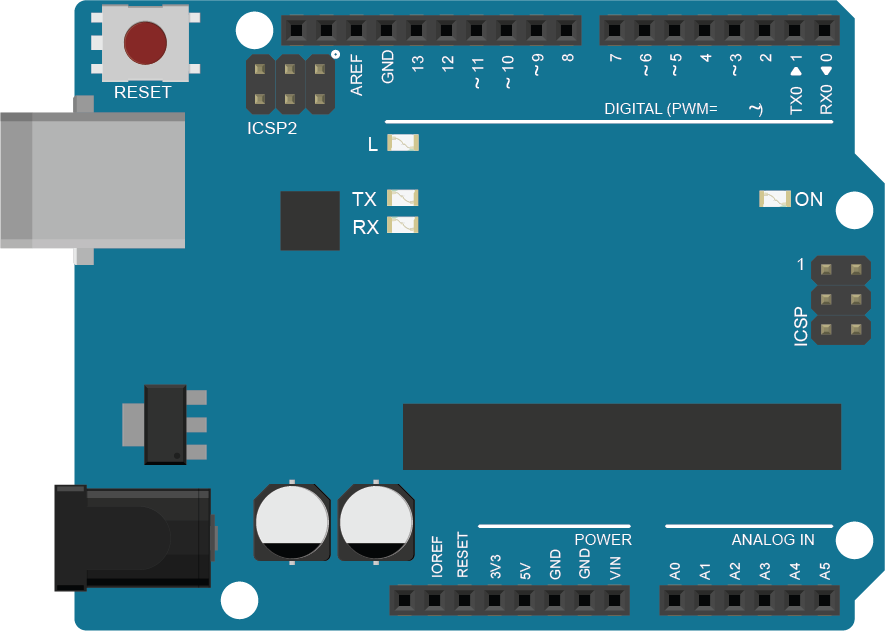

Representation of an Arduino Uno board - created using files from [fritzing-parts](https://github.com/fritzing/fritzing-parts/)

The board presented above is an Arduino UNO, which presents:

- 14 **digital** input & output (I/O) pins numbered D0 to D13

- 6 **analog** input pins numbered A0 to A5

Of the 14 digital pins, 6 are capable of **PWM **(Pulse Width Modulation). The **analog**, **digital**, and **PWM **are the three fundamental signals natively supported by the Arduino board. You might have been presented with a different type of board which will present a different pin configuration.

It is important to know your hardware and understand the configuration of your board. In the next three exercises, you will identify the different pins your board offers.

 **Exercise.** List your device's **digital** pins in the following edit field; digital pin two should be noted **D2**; the different pins can be indifferently separated by commas or space.

myDigitalPins = "";
try
    myDigitalPins = eval(myDigitalPins); %#ok<EVLCS>
    myDigitalPins = join(myDigitalPins);
catch
end
 
IdentifyDigitalPin(myDigitalPins);

 **Exercise.** List the **analog** pins on your device in the following edit field; analog pin 2 should be noted A**2**; the different pins can be separated by commas or spaces indifferently.

myAnalogPins = "";
try
    myAnalogPins = eval(myAnalogPins); %#ok<EVLCS>
    myAnalogPins = join(myAnalogPins);
catch
end
 
IdentifyAnalogPin(myAnalogPins);

 **Exercise.** List the pins that are PWM enabled; the pins should be noted as in the previous two exercises; the different pins can be entered separately by commas or spaces indifferently.

myPWMPins = "";
 
IdentifyPWMPin(myPWMPins);

Another useful way to identify the pins on your Arduino board is to open the Arduino Explorer app. It can be done by running the command:

or by finding the Arduino Explorer app in the **Apps **tab in the MATLAB Toolstrip.

A board connected to your computer should be visible on the app's opening page. Select your Arduino Board and access the board's pinout in the bottom right corner of the app.

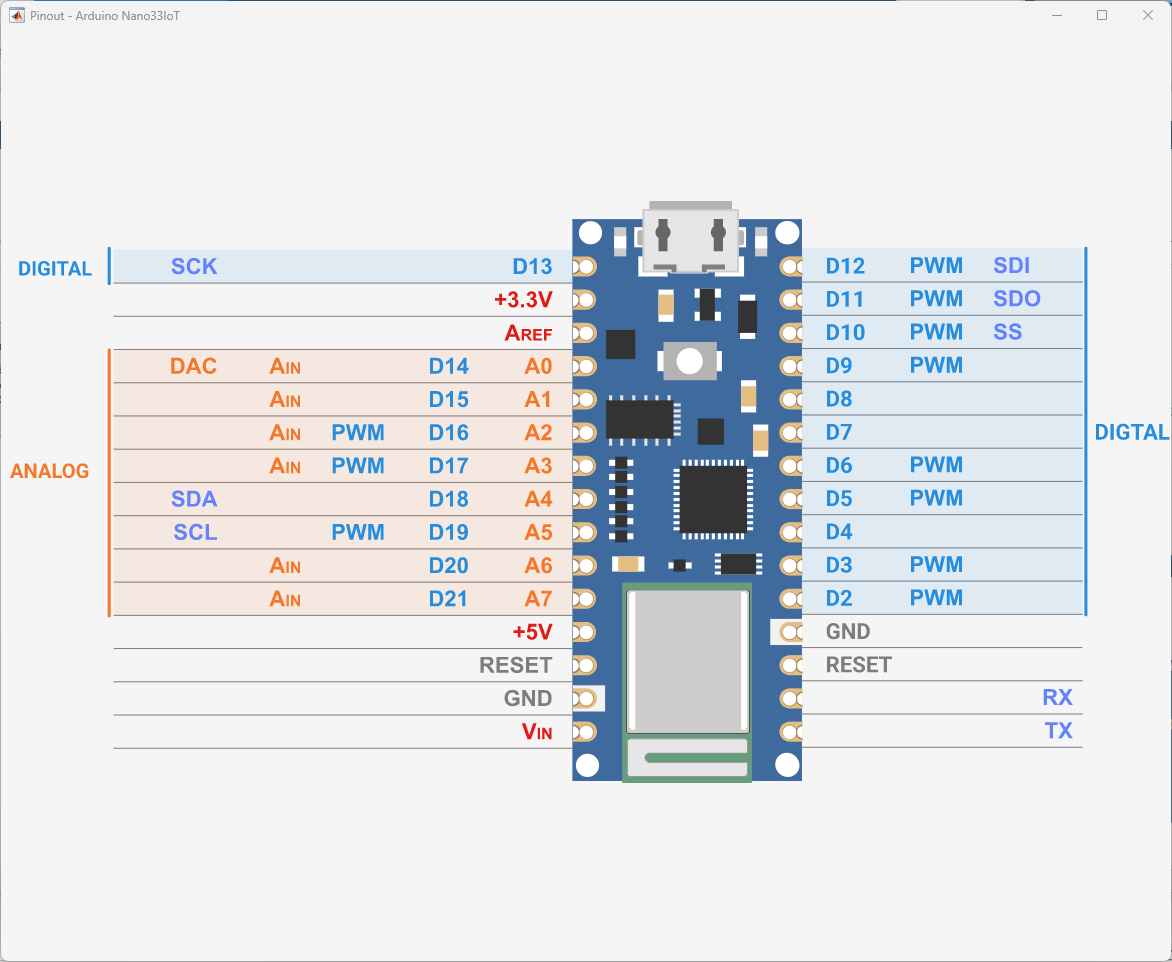

Example of the Pinout from an Arduino Nano IoT

## Signals

As presented in the previous section, your Arduino supports three types of signal: analog, digital, and PWM. The analog signal can only be used as an input signal, such as reading data from a sensor. The PWM signal can only be used as an output to control multiple kinds of hardware. The digital signal can be used as both input and output.

### Analog Signals

An analog signal is any continuous signal with an unlimited range of values. They are straight and not discrete. The amplitude of an analog signal may vary with time, making it a natural representation of real-world phenomena. An example of an analog signal would be the temperature measured by a weather station concerning time.

  **Try. **Visualize the temperature at the Mathworks' weather station in Natick, MA, over the last 24 hours.

 Visualize yesterday's temperature from a weather station at Mathworks campus in Natick, MA.

 
visualizeNatickWeather()

Microcontrollers cannot directly process analog signals because microcontrollers are designed to work with digital signals. Analog signals are continuous and can have infinite values, while microcontrollers operate on discrete digital values (0s and 1s). To enable microcontrollers to work with analog signals, the analog signals need to be encoded into digital form using techniques like analog-to-digital conversion (ADC). The encoding process samples the analog signal over multiple digital signals called bits.

For example: 

- A single-bit signal comprises one digital signal and can only take two values, 0 and 1.

- A two-bit signal is composed of two digital signals and can take four values: 00, 01, 10, and 11.

- A 8 bits signal is composed of eight digital signals and can take $2^8=256$ values: 00000000, 00000001, 00000010, etc.

Additionally, an analog signal could be encoded over 8 bits by assuming:

- $00000000$ to represent the lowest value that the analog signal can take.

- $11111111$ To represent the highest value that the analog signal can take.

- Every other combination of bits represents an intermediate state of the analog signal.

  **Try. **Modify the following control of the encoding to understand how the microcontroller reads analog signals.

 
encodeAnalogSignal(...
0,... % Minimum value
200,... % Maximum vale
4); % Number of bits


### **Digital signals**

A digital signal is a logical signal that can only take two values: 0 and 1, or LOW and HIGH.

  **Try. **Visualize the air relative humidity in Natick, MA, over the last 24 hours.

 
plotHumidity

 **Exercise.** What type of signal is the humidity?

IdentifyHumidityType("None");

One way to transform an analog signal into a digital signal is to apply logical operation. For example, we could create a digital that would be HIGH (or 1) when humidity surpasses a certain value and LOW (or 0) below that value. 

  **Try. **Visualize yesterday's temperature from a weather station at Mathworks campus in Natick, MA.

 
filteringHumidity(">"," 50")

From reading an analog signal representing the relative air humidity, we can now define a digital signal that could control a dehumidifier to keep a comfort level inside a home.

 **Reflect.** Can you think of an everyday digital signal? Example: low gas tank signal on your car's dashboard.

### PWM (Pulse Width Modulation) signal

Pulse Width Modulation (PWM) is another digital signal that can be sent using an Arduino board. PWM signal allows for the modulation of the duty cycle of a signal, resulting in variable signal output between HIGH and LOW states. PWM signals are high-frequency (~ 500 Hz) square wave signals.

  **Try. **Use the control below to visualize the PWM signal with a different duty cycle

 
visualizePWM(25)

## Control an LED with Arduino board

In this section, we will explore how to wire an LED to an Arduino board and how to control it using three different computing workflows.

 **Exercise.** Based on what you have learned before, what kind of signal appears most adequate to control an LED?

signalForLED("Nonde");

### Wiring schematic

To follow this part of the script, you will need the following:

- An Arduino board (here we are presenting with Arduino UNO)

- An LED

- A 330 Ohm resistor

- Two male-male jumper wires (might differ with other boards)

- A small breadboard

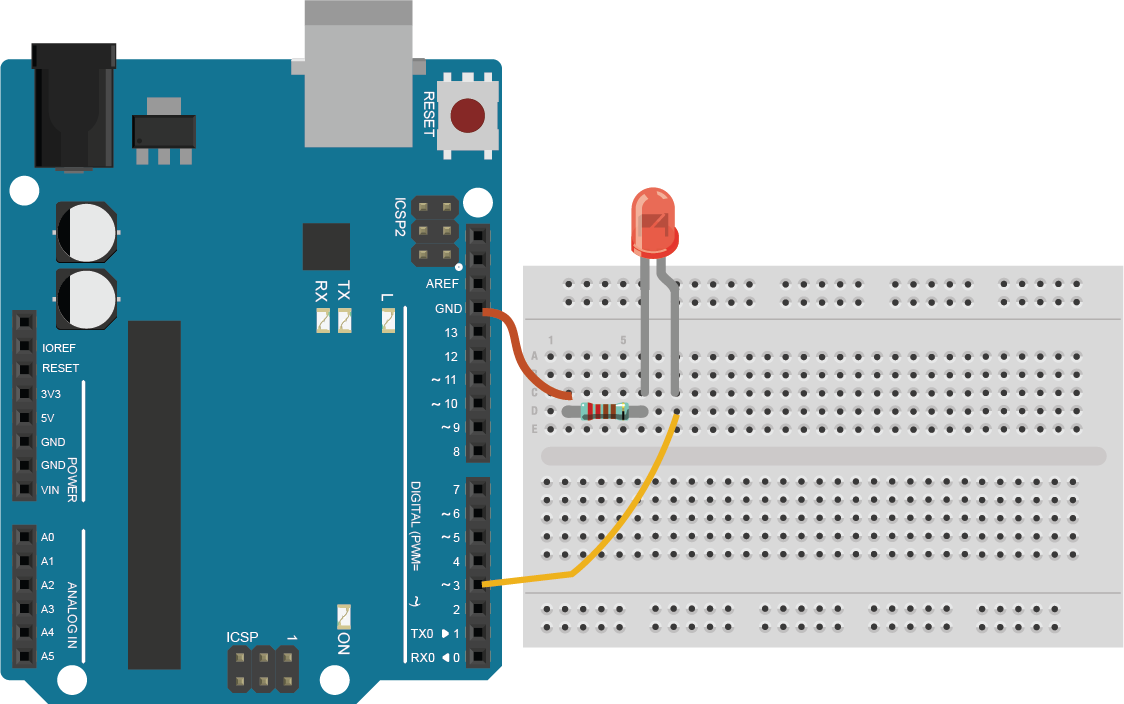

Wiring diagram with one LED - created using files from [fritzing-parts](https://github.com/fritzing/fritzing-parts/)

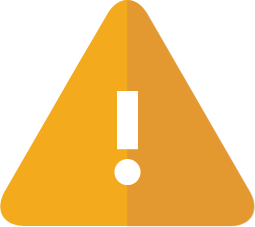  It is crucial to consider the polarity when wiring and LED, as reversing the polarity can lead to damage or complete failure of the component. To avoid such problems, always ensure that the anode ($+$) is connected to the positive side and that the cathode, the shorter leg, is connected to the negative side. Visible indicators like a flat side on the LED casing or a noth may be present to help you identify the correct polarity of an LED:

- The shorter leg is negative, the longer leg is positive

- The flat side is negative, and the rounded side is positive

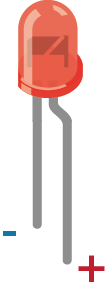

A breadboard is a prototyping tool to create and test electronic circuits without soldering. It consists of a grid of holes connected by conductive metal strips. Attached below are pictures of a breadboard with exposed metal strips.

### Tests wiring

We used the Arduino Explorer app to access the pinout diagram of our Arduino board. The application itself can be used for many more applications. Here, we will be using it to test the wiring of our LED. Remember that you can access the Arduino Explorer app by typing the following command on your Command Window:

or by finding the Arduino Explorer app in the **Apps **tab in the MATLAB Toolstrip.

  **Try.** Follow this step to turn on the LED.

- Select your Arduino board in the available hardware section

- Select the Digital pin that controls your LED

- In the **Pin Configuration **window, select **Digital Output (Write)**

- Modify the **write value** in the **Pin Explorer** to 1

### Control the LED with MATLAB

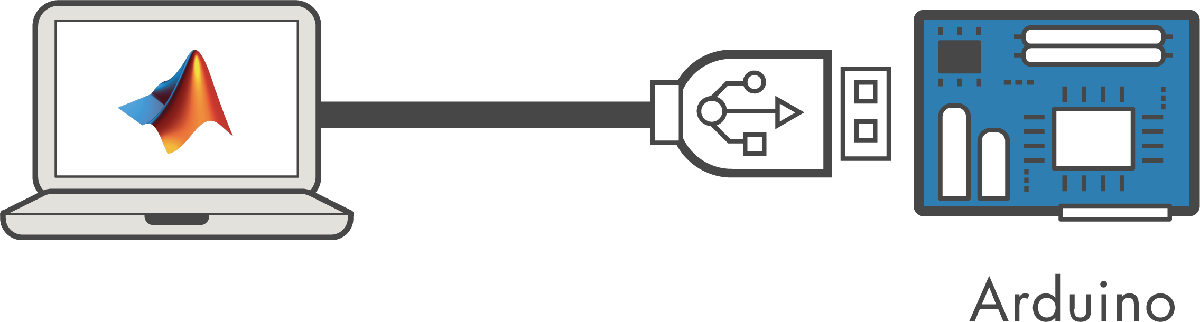

Now that you tested your wiring, you should have been able to turn on the LED using the Arduino Explorer App. An easy way to connect your Arduino hardware with MATLAB is to generate MATLAB code from the Arduino Explorer App automatically. 

  **Try.** In the Arduino Explorer App, click the **Generate script **button in the toolstrip to generate code to turn on the LED. The generated code should look like the following (disregarding the text part of the live script):

** Close all sessions of the Arduino Explorer app.**

 **Try.** After saving the file generated in the Arduino Explorer app, select the script in the file selector below to start running line by line. Click the **CONTINUE **  in the toolstrip to run to the next line.

myLEDPin = runGeneratedCode("",myPWMPins);

 **Exercise.** What happens when the Arduino object is deleted (last line of code)?

checkArdObjDeleted(0)

 **Exercise.** What would happen if all the line of code from the generated script was run simultaneously (**RUN **button in the toolstrip)?

checkRunGeneratedCode(0)

### Control the LED with Simulink

In the previous section, you have learned about two ways to control your Arduino hardware with MATLAB: using the Arduino Explorer App and through the `arduino `command. This section will test two Simulink workflows to control your Arduino Hardware.

#### **Run on board (External mode)** 

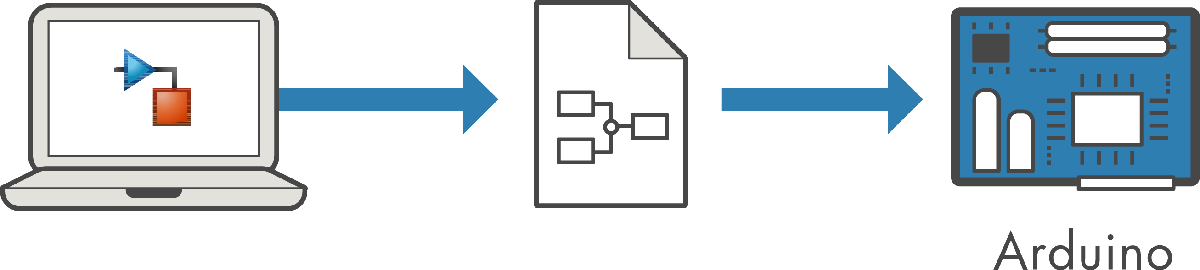

Use your Simulink model to generate code deployed onto your Arduino hardware. Then the Arduino board can run the code without any operation from MATLAB or Simulink. The board could be unplugged from your computer and powered through any power supply and would run the code.

#### Example: Blink an LED (External mode)

In this example, we will start from a blank Simulink model and make the LED you previously connected to the computer blink.

 **Try.** Create an empty Simulink model.

 
if ArduinoStatus == 1
    BlinkLED = new_system;
    set_param(BlinkLED,'HardwareBoard',myBoard)
    open_system(BlinkLED)
else
    BlinkLED = [];
end

 **Exercise.** Add a **Pulse Generator** block to create a blinking signal:

- Open the **Library Browser **from the **SIMULATION** tab in the toolstrip.

- Drag and drop the **Pulse Generator** from the **Simulink > Sources** library.

- Double-click the **Pulse Generator **to set the Amplitude to 1, Period to 1 sec, and Pulse Width to 50 %.

  checkPulseGenerator(BlinkLED)

 **Exercise.** Add a **Digital Output** block to control the LED:

- Open the **Library Browser **from the **SIMULATION** tab in the toolstrip.

- Drag and drop the **Digital Output **block from the **Simulink Support Package for Arduino Hardware > Common **library.

- Set the **Pin number **to the pin on which you connected your LED to the board.

- Connect the **Pulse Generator** to the **Digital Output**

  checkDigitalOutput(BlinkLED,myLEDPin);

 **Try.** In the **HARDWARE** tab in the toolstrip, click the **Build, Deploy & Start button ** **, **observe the LED blinking

 **Try.** Unplug the Arduino from this computer and connect it to an independent power source (for example, USB charger); observe that the LED is still blinking.

Unlike the MATLAB workflow presented in the previous sections. Once the code is deployed onto the hardware, there is no need to keep a connection between Simulink and your Arduino board for your code to run.

#### Connected I/O (inputs/outputs mode)

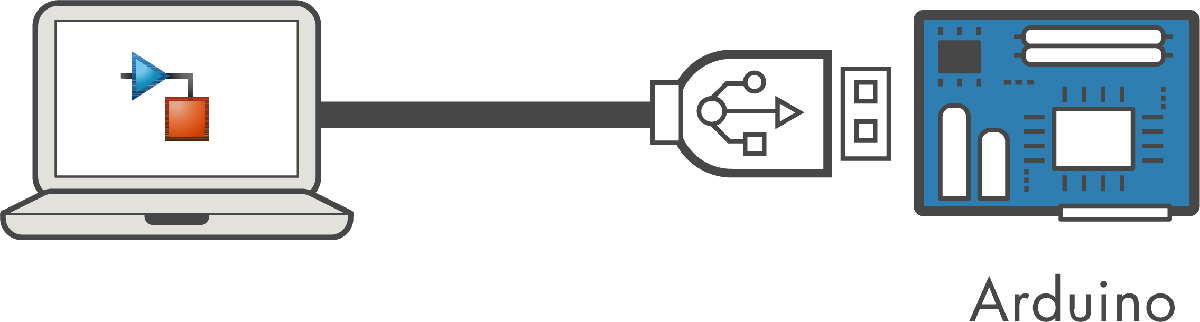

The connected I/O workflow allows Simulink to take control of your Arduino board; it can read the signal from the input pins and write signals in the output pins. The signals can be monitored as the simulation runs, but the code is run on your local computer.

#### Example: Connected I/O (inputs/outputs mode)

As a promising young engineer working for ACME Corp, you are tasked to thoroughly investigate a new machine that has caused multiple accidents since it was installed a few months ago. The new machine replaced an old-fashioned one and was supposed to boost productivity by over 70%. Due to the many accidents, the production line has been stopped many times, and productivity is dropping.

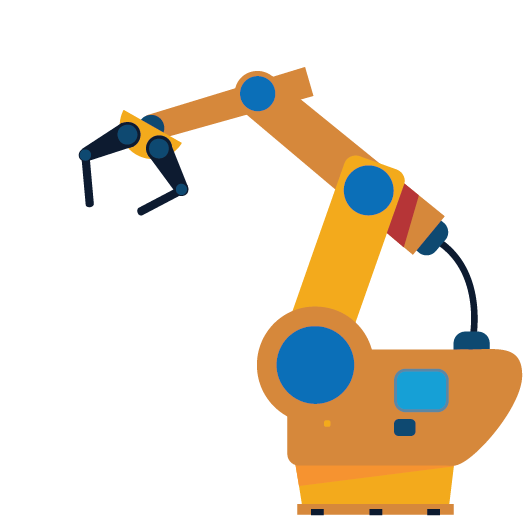

An example of a dangerous machine

After much consideration, the investigation concluded that incorporating a visual signal to alert the nearby operator of the machine's operation is the most viable solution. As the engineer in charge of the project, you choose to use an Arduino Board to control the build light while the machine is in operation. In the development phase, you use a simple LED to model the bulb and test your setup.

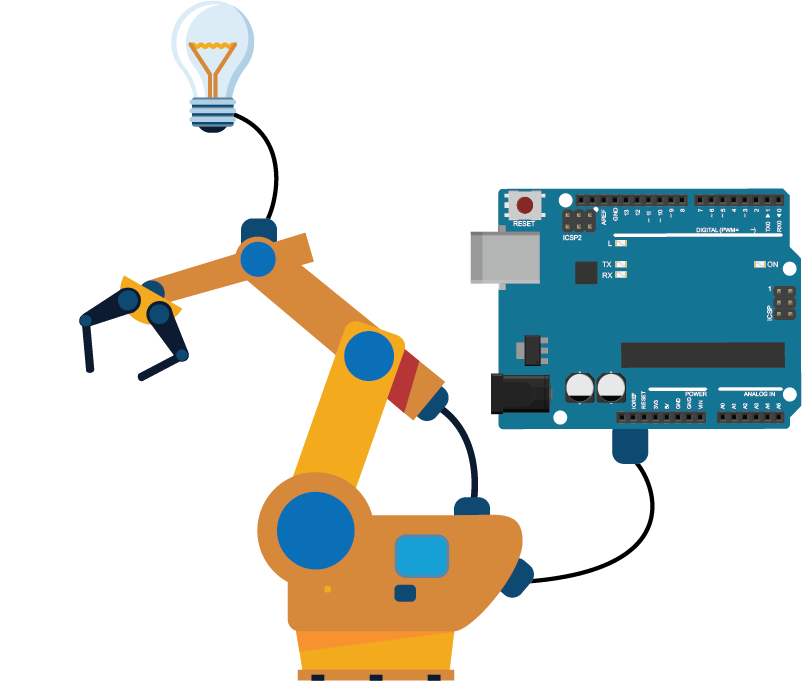

Final setup with Arduino and lightbulb - created using files from [fritzing-parts](https://github.com/fritzing/fritzing-parts/)

This script requires you to have access to one of the Arduino boards supported by the MATLAB and Simulink support packages for Arduino Hardware. Please, refer to [SupportArduino.mlx](matlab:open('./SupportArduino.mlx')) to check your hardware compatibility and installation of the support package.

In this example, we will create a smart LED whose brightness is controlled based on the ambient light captured by a photoresistor. To follow this part of the script, you will need:

- An Arduino board (here we are presenting with Arduino UNO)

- An LED

- A 330$~\Omega$ resistor

- A 1$~\text{k}\Omega$ resistor

- A small photoresistor

- Seven male-male jumper wires (needs might differ with other boards)

- A small breadboard

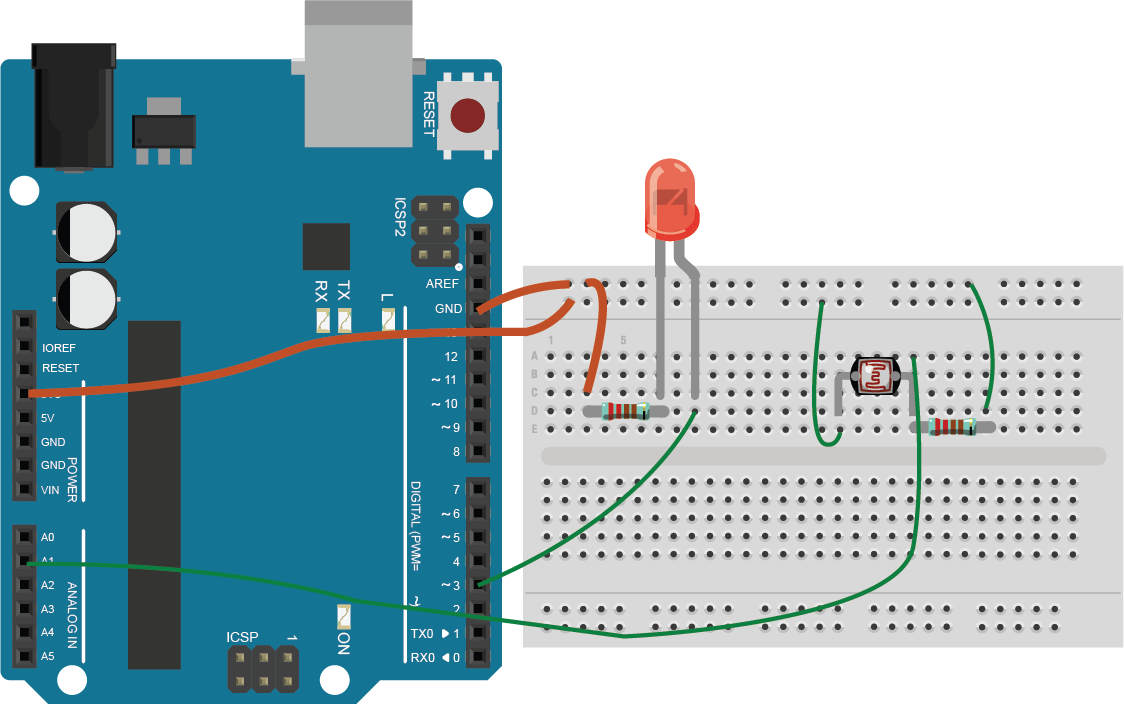

Wiring diagram with one LED and one photoresistor - created using files from [fritzing-parts](https://github.com/fritzing/fritzing-parts/)

Note that the resistor associated with the LED is the 330 Om resistor, and the one kOhm resistor is related to the photoresistor.

 **Exercise.** What analog pin did you connect your photoresistor?

myPhotoPin = "";
if contains(myPhotoPin,"A")
    wrappedDisp("Your photoresistor is connect to "+myPhotoPin+".")
else
    warning("Please connect your photoresistor to an analog pin.")
end
myPhotoPin = extractAfter(myPhotoPin,"A");
myPhotoPin = str2double(myPhotoPin);

 **Try.** Open CalibratePhotoresistor, and observe the value of the display.

% Open system and preset board:
smartLED = load_system(fullfile("Models","CalibratePhotoresistor"));
set_param(smartLED,'HardwareBoard',myBoard)
open_system("CalibratePhotoresistor")

% Pre-set analog input pin
block = Simulink.findBlocks(smartLED);
blockname = getfullname(block);
blockname = string(blockname);
blockname = replace(blockname,newline,"");
idblock = contains(blockname,"Analog Input");
block = block(idblock);
if ~isnan(myPhotoPin)
    set_param(block,"pinNumber",string(myPhotoPin))
end

% Pre-set the digital output pin
block = Simulink.findBlocks(smartLED);
blockname = getfullname(block);
blockname = string(blockname);
blockname = replace(blockname,newline,"");
idblock = contains(blockname,"Digital Output");
block = block(idblock);
set_param(block,"pinNumber",string(myLEDPin))
 

 **Exercise.** Click  **Run with IO** in the toolstrip's **HARDWARE **tab to start the model. Completely cover the photoresistor and report the value read by the photoresistor.

coveredValue = [ ];
if coveredValue < 100 %#ok<BDSCI>
    wrappedDisp("Your photoresistor reads "+num2str(coveredValue)+".")
elseif isempty(coveredValue)
    warning("Please enter the value read by your photoresistor while covering it.")
else
    warning("The value should be lower, please verify the wiring diagram and try again.")
end

 **Exercise.** Use your phone flashlight directly onto the photoresistor and report the value read by the photoresistor. Once done, click **Stop **in the toolstrip to stop the model.

flashedValue = [ ];
if flashedValue > 600 %#ok<BDSCI>
    wrappedDisp("Your photoresistor reads "+num2str(flashedValue)+".")
elseif isempty(flashedValue)
    warning("Please enter the value read by your photoresistor while covering it.")
else
    warning("The value should be higher, please verify the wiring diagram and try again.")
end

Based on those values, we can create a mathematical function that will transform the value read by the photoresistor into an index of brightness, 0%, meaning the photoresistor is covered, and 100% indicates the ambient light is at its maximum.

 **Try.** Click the following button for a brightness control function example.

 
x = 0:1024;
y = (x-23)/(850-23);
y = min(y,1);
y = max(y,0)*100;
plot(x,y,LineWidth=2)
xlim([0 1024])
ylim([-5 105])
xlabel("Value read by photoresistor")
ylabel("Ambient brightness")

 **Try.** Open SmartLED, click **Run with IO**, and observe the behavior of the LED as the ambient light changes.

 
% Open system and preset board:
smartLED = load_system(fullfile("Models","SmartLED"));
set_param(smartLED,'HardwareBoard',myBoard)
open_system("SmartLED")

% Pre-set analog input pin
block = Simulink.findBlocks(smartLED);
blockname = getfullname(block);
blockname = string(blockname);
blockname = replace(blockname,newline,"");
idblock = contains(blockname,"Analog Input");
block = block(idblock);
if ~isnan(myPhotoPin)
    set_param(block,"pinNumber",string(myPhotoPin))
end

% Pre-set the digital output pin
block = Simulink.findBlocks(smartLED);
blockname = getfullname(block);
blockname = string(blockname);
blockname = replace(blockname,newline,"");
idblock = contains(blockname,"Digital Output");
block = block(idblock);
if ~isnan(myLEDPin)
    set_param(block,"pinNumber",string(myLEDPin))
end

% Pre-set the LowValue output pin
block = Simulink.findBlocks(smartLED);
blockname = getfullname(block);
blockname = string(blockname);
blockname = replace(blockname,newline,"");
idblock = contains(blockname,"LowValue");
block = block(idblock);
if ~isempty(coveredValue)
    set_param(block,"Value",string(coveredValue))
end

% Pre-set the digital output pin
block = Simulink.findBlocks(smartLED);
blockname = getfullname(block);
blockname = string(blockname);
blockname = replace(blockname,newline,"");
idblock = contains(blockname,"HighValue");
block = block(idblock);
if ~isempty(flashedValue)
    set_param(block,"Value",string(flashedValue))
end

## Further Exploration: Emergency Signal Morse Code

In this last example, we will control our Arduino from MATLAB to send Morse code with the LED.

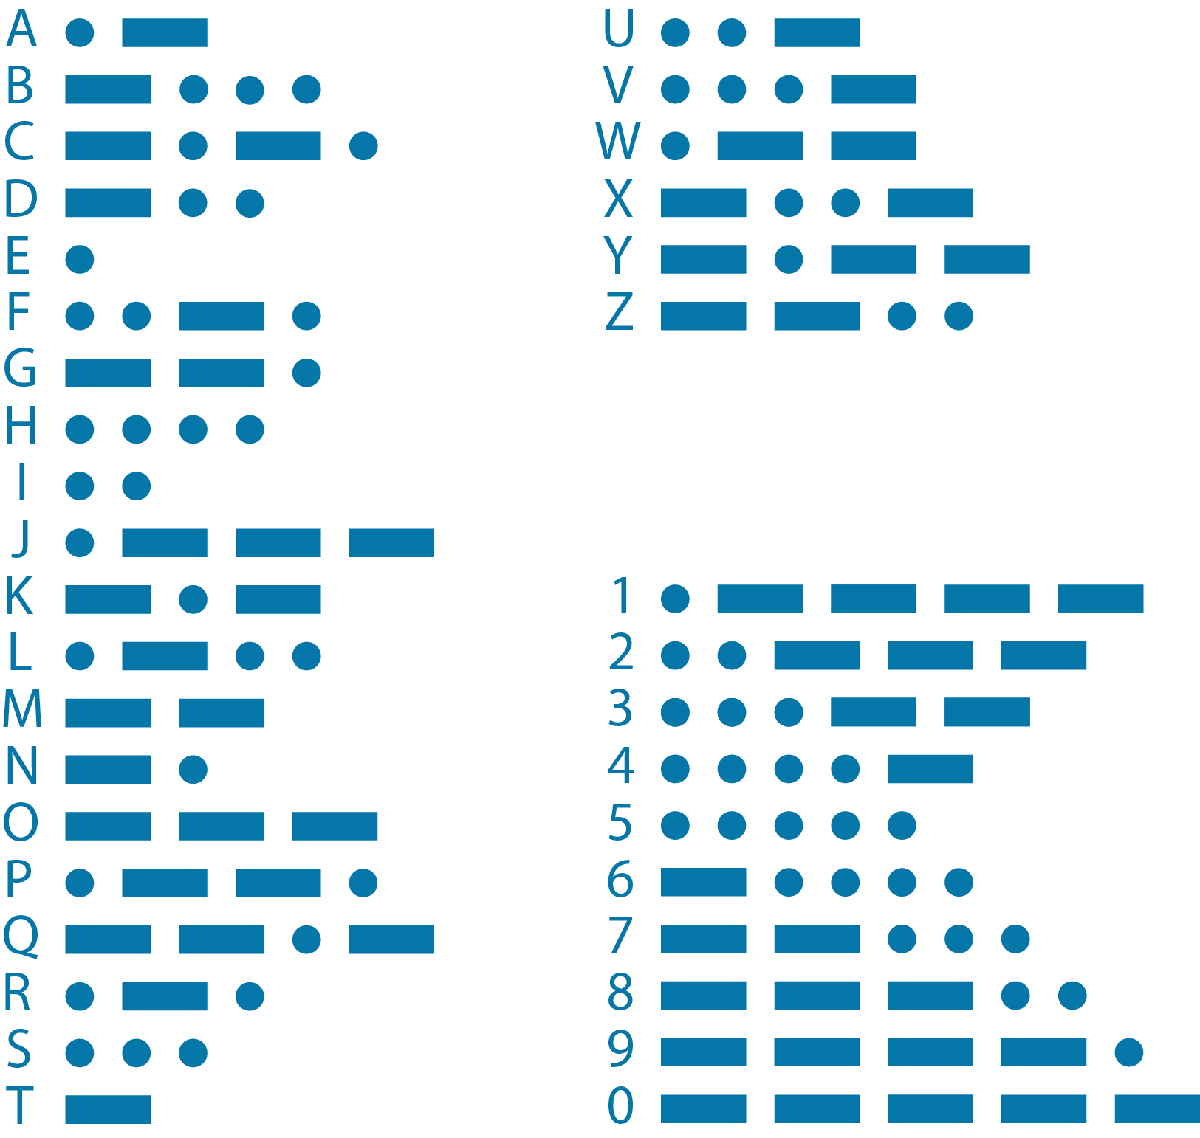

International Morse code - retrieved from [Wikimedia](https://commons.wikimedia.org/wiki/File:International_Morse_Code.svg)

Morse code transforms each character into a sequence of short and long flashes of light. It has been used in [many telecommunication applications ](https://en.wikipedia.org/wiki/Morse_code) including the telegraph. Sending a message using Morse code can be done by:

- Encoding the message

- Transmitting the signal

- Decoding the signal

In this script, we will encode and transmit a signal through the LED connected to our Arduino.

### Encoding in Morse

The Morse code for each character in the English alphabet can be found in the Data folder in the file called MorseCode.mat.

 **Try.** Open and display the Morse code table.

 
load Data\MorseCode.mat morseCode
morseCode

You can notice that the characters "." and "-" respectfully depict the short and long flashes of light that we want to transmit with LED.

 **Try.** Use the following edit field to enter the message you want to encode.

InputString = "SOS";
EncodedString = replace(upper(InputString),morseCode.CHAR,morseCode.SEQU);
EncodedString

## Transmitting the Morse code

Morse code is generally defined so the long flashlight will be three times longer than the short flashes, and each pause between the flashes is the same length as the brief flashes. We can refer to this as the base time length of the Morse code.

 **Try.** Define the base time length you want to use.

baseTimeLength = 0.5;

Before sending the encoded signal to the Arduino, we test that the Arduino is available and ready to transmit.

 **Try.** Click the following button to test your Arduino Hardware.

 
if ArduinoStatus == 1
    arduinoObj = arduino;
    configurePin(arduinoObj, "D"+myLEDPin, "DigitalOutput");
    writeDigitalPin(arduinoObj, "D"+myLEDPin, 1);
    pause(baseTimeLength)
    clear arduinoObj
end

Your Arduino's LED should have turned on for the duration of the base length time you selected.

Now that the hardware has been tested, we can send the signal to the Arduino. We are adding the option to repeat the signal multiple times.

 **Try.** Click the following button to transmit the signal; you can also repeat the signal multiple times and tune the base time length.

 
baseTimeLength = 0.5;

if ArduinoStatus == 1
    arduinoObj = arduino;
    configurePin(arduinoObj, "D"+myLEDPin, "DigitalOutput");
    for n = 1:1
        for i = 1:strlength(EncodedString)
            character = extract(EncodedString,i);
            switch character
                case "."
                    writeDigitalPin(arduinoObj, "D"+myLEDPin, 1);
                    pause(1*baseTimeLength);
                case "-"
                    writeDigitalPin(arduinoObj, "D"+myLEDPin, 1);
                    pause(3*baseTimeLength)
                case " "
                    writeDigitalPin(arduinoObj, "D"+myLEDPin, 1);
                    pause(7*baseTimeLength)
            end
            writeDigitalPin(arduinoObj, "D"+myLEDPin, 0);
            pause(1*baseTimeLength)
        end
    pause(1)
    end
    clear arduinoObj
end

 **Try.** If you want to learn more about how this was implemented, you can switch the view to expose the code encoding and transmitting the Morse code with your Arduino.

Modifying the encoding

 **Try.** Use the following edit field to enter the message you would like to "MAYDAY!"

InputString = "SOS";
EncodedString = replace(upper(InputString),morseCode.CHAR,morseCode.SEQU);
EncodedString

 Exercise**.** Search the morse code for "!" online and add it to the table.

morseCode{end+1,:} = ["",""];
[~,idx] = unique(morseCode.CHAR);
 
morseCode = morseCode(idx,:)
% XXX Add check

 **Try.** Add all the other characters that you would like to 

morseCode{end+1,:} = ["",""];
[~,idx] = unique(morseCode.CHAR);
 

 **Try.** Encoding your message again.

InputString = "SOS";
EncodedString = replace(upper(InputString),morseCode.CHAR,morseCode.SEQU);
EncodedString

## Conclusion

In this script, you learned about :

- the different types of signals used by an Arduino board

- the different workflow to program and control Arduino hardware with MATLAB and Simulink

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

## Helper Functions

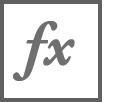`IdentifyDigitalPin`

function IdentifyDigitalPin(myDigitalPins)

% Pre-process student answer:
myDigitalPins = strtrim(split(myDigitalPins, [" ", ","]));
myDigitalPins = sort(unique(myDigitalPins));
myDigitalPins(myDigitalPins == "") = [];

if ArduinoStatus == 1
    try
        arduinoObj = arduino;
        availablePins = arduinoObj.AvailablePins;
        availablePins = cellfun(@string,availablePins)';
        availablePins = availablePins(contains(availablePins,"D"));
        availablePins = strtrim(split(availablePins, [" ", ","]));
        availablePins = [availablePins; "D0"; "D1"];
        availablePins = sort(unique(availablePins));
        
        
        if length(availablePins) == length(myDigitalPins)
            if availablePins == myDigitalPins
                wrappedDisp("Good job! You have identified the pins correctly.")
            else
                warning("Some of the pins you have identified are wrong.")
            end
        else
            if ~any(contains(myDigitalPins, "D0")) || ~any(contains(myDigitalPins, "D1"))
                warning("You are missing some pins. Hint: Sometime the pins D0 and D1 are indicated with the RX and TX marking.")
            else
                warning("You are missing some pins. Hint: Check both side of the board.")
            end
        end
        clear arduinoObj
    catch
        clear arduinoObj
    end
end

end

`IdentifyAnalogPin`

function IdentifyAnalogPin(myAnalogPins)
% Pre-process student answer:
myAnalogPins = strtrim(split(myAnalogPins, [" ", ","]));
myAnalogPins = sort(unique(myAnalogPins));
myAnalogPins(myAnalogPins == "") = [];

if ArduinoStatus == 1
    try
        arduinoObj = arduino;
        availablePins = arduinoObj.AvailablePins;
        availablePins = cellfun(@string,availablePins)';
        availablePins = availablePins(contains(availablePins,"A"));
        availablePins = strtrim(split(availablePins, [" ", ","]));
        availablePins = sort(unique(availablePins));
        
        if length(availablePins) == length(myAnalogPins)
            if availablePins == myAnalogPins
                wrappedDisp("Good job! You have identified the pins correctly.")
            else
                warning("Some of the pins you have identified are wrong.")
            end
        elseif length(availablePins) > length(myAnalogPins)
            warning("You are missing some pins. Hint: Check both side of the board.")
        elseif length(availablePins) < length(myAnalogPins)
            warning("You entered too many pins. Hint: Check both side of the board.")
        end
        clear arduinoObj
    catch
        clear arduinoObj
    end
end
end

`IdentifyPWMPin`

function IdentifyPWMPin(myPWMPins)
% Pre-process student answer:
myPWMPins = strtrim(split(myPWMPins, [" ", ","]));
myPWMPins = sort(unique(myPWMPins));
myPWMPins(myPWMPins == "") = [];

if ArduinoStatus == 1 
    try
        arduinoObj = arduino;
        availablePins = arduinoObj.AvailablePWMPins;
        availablePins = cellfun(@string,availablePins)';
        availablePins = strtrim(split(availablePins, [" ", ","]));
        availablePins = sort(unique(availablePins));
        
        if length(availablePins) == length(myPWMPins)
            if availablePins == myPWMPins
                wrappedDisp("Good job! You have identified the pins correctly.")
            else
                warning("Some of the pins you have identified are wrong.")
            end
        elseif length(availablePins) > length(myPWMPins)
            warning("You are missing some pins. Hint: Check both side of the board.")
        elseif length(availablePins) < length(myPWMPins)
            warning("You entered too many pins. Hint: Check both side of the board.")
        end
        clear arduinoObj
    catch
        clear arduinoObj
    end
end
end

`IdentifyHumidityType`

function IdentifyHumidityType(signalType)
    switch signalType
        case "None"
            warning("Please select either Analog or Digital")
        case "Analog"
            wrappedDisp("Good job! Just like the temperature signal signal"+...
                " was analog, the humidity signal is analog.")
        case "Digital"
            warning("Incorrect! Hint: the humidity signal is similar to the "+...
                " temperature signal.")
    end
end

`signalForLED`

function signalForLED(signalType)
    switch signalType
        case "None"
            warning("Please one of the other options.")
        case "Analog"
            warning("The analog pins on your Arduino can only be used for input signal,"+...
                " not to control other hardware.")
        case "Digital"
            wrappedDisp("Good job! A digital signal from a digital pins can be used to turn on"+...
                " and off and LED. You could also used the PWM pin to control the brightness.")
        case "PWM"
            wrappedDisp("Good job! A PWM signal from a digital pins can be used to turn on"+...
                " and off and LED and control the brightness. A simpler option would be"+...
                " to use a digital pin and lose the brightness control.")
    end
end

`checkPulseGenerator`

function checkPulseGenerator(sim)
    numblocks = length(Simulink.findBlocks(sim));
    if numblocks ~= 1
        warning("You should only have one block on your simulink model at the moment.")
    else
        blockname = getfullname(Simulink.findBlocks(sim));
        blockname = string(blockname);
        blockname = replace(blockname,newline,"");
        if contains(blockname,"PulseGenerator")
            Amplitude = str2double(get_param(getfullname(Simulink.findBlocks(sim)),"Amplitude"));
            Period = str2double(get_param(getfullname(Simulink.findBlocks(sim)),"Period"));
            PulseWidth= str2double(get_param(getfullname(Simulink.findBlocks(sim)),"PulseWidth"));
    
            check = 0;
            % Check Amplitude
            if Amplitude ~= 1
                warning("The amplitude of your pulse generator should be 1.")
            else
                check = check + 1;
            end
    
            % Check Period
            if Period ~= 1
                warning("Your pulse generator period should be set to 1.")
            else
                check = check + 1;
            end
    
            % Check Pulse Witdh
            if PulseWidth ~= 50
                warning("Your pulse generator pulse width should be set to 50 (%).")
            else
                check = check + 1;
            end
    
            if check == 3
                wrappedDisp("Good job! You defined you pulse generator correctly.")
            end
        else
            warning("The block you inserted on the model is not a Pulse Generator.")
        end
    end
end

`isProjectLoaded`

function y = isProjectLoaded()

    try
        proj = currentProject();
        currentFolder = string(pwd);
        if contains(currentFolder,proj.RootFolder)
            y = true;
        else
            y = false;
        end
    catch
        y = false;
    end
    
end

`hardwareTest`

function hardwareTest(myBoard)

    % Check if project is loaded
    if ~isProjectLoaded
        warning('Please load the project, intro-to-engineering.prj')
    end
    
    % Check if is online
    if IsOnline
        warning("You are currently running this script on MATLAB Online.")
        warning("Follow the instruction in <a href="+char(34)+...
            "matlab:open README.mlx"+char(34)+">README.mlx</a> to run this module on MATLAB Desktop.")
    end
    
    % Check for MATLAB support package
    errpkg = false;
    myAddons = matlab.addons.installedAddons().Name;
    if ~any(contains(myAddons,"MATLAB Support Package for Arduino Hardware"))
        errpkg = true;
    end

    % Check for MATLAB support package
    if ~any(contains(myAddons,"Simulink Support Package for Arduino Hardware"))
        errpkg = true;
        
    end


    if errpkg
        warning(['You are missing the MATLAB or Simulink Support Package for Arduino Hardware' newline....
            newline 'Follow the instruction in SupportArduino.mlx']);
    end
    
    %Check what arduino is connected
    if ~errpkg
        ArduinoStatus(Verbose=true);
    end

end

`getWeatherData`

function weatherData = getWeatherData()

    [data,time,~] = thingSpeakRead(12397,'DateRange',[datetime('now')-days(1),datetime('now')]);
    weatherData = timetable(time,data);
    weatherData = splitvars(weatherData,'data');
    weatherData.Properties.VariableNames = {'WindDir','WindSpeed','Humidity','Temperature',...
        'Rain','Pressure','PowerLevel','LightIntensity'};
    weatherData = retime(weatherData,"regular","mean","TimeStep",minutes(15));
    [weatherData,~] = fillmissing(weatherData,"linear");

end

`visualizeNatickWeather`

function visualizeNatickWeather()
    weatherData = getWeatherData;
    
    figure
    plot(weatherData.time,weatherData.Temperature,LineWidth=2)
    xlabel("Date")
    ylabel("Temperature ( $^\circ$F )",Interpreter="latex")
    title("Past 24 hours weather in Natick, MA")
end

`encodeAnalogSignal`

function encodeAnalogSignal(minSignal,maxSignal,numBin)

    weatherData = getWeatherData;
    
    figure
    plot(weatherData.time,weatherData.Temperature,LineWidth=2)
    xlabel("Date")
    ylabel("Temperature ( $^\circ$F )",Interpreter="latex")
    title("Yesterday's weather in Natick, MA")
    
    digitalMap = linspace(minSignal,maxSignal,2^numBin);
    analogSignal = weatherData.Temperature;
    [~,I] = min(abs((analogSignal - digitalMap)'));
    hold on
    plot(weatherData.time,digitalMap(I))
    hold off
    legend('Analog signal','Encoded Signal','Location','best')
    title("Comparison analog/digital signals")
    
end

`plotHumidity`

function plotHumidity()
    
    weatherData = getWeatherData;

    figure
    plot(weatherData.time,weatherData.Humidity,LineWidth=2)
    ylabel("Relative Humidity (%)")
    xlabel("Date")
    title("Relative humidity in Natick, MA over the last 24 hours")
end

`filteringHumidity`

function filteringHumidity(operator,level)
    
    weatherData = getWeatherData;

    figure
    plot(weatherData.time,weatherData.Humidity,LineWidth=2)
    yyaxis left
    ylabel("Relative Humidity (%)")
    xlabel("Date")
    title("Yesterday's relative humidity in Natick, MA")
    yyaxis right
    filteredHumidity = eval("weatherData.Humidity "+operator+level);
    stairs(weatherData.time,filteredHumidity,LineWidth=1)
    yticks([0 1])
    yticklabels(["LOW","HIGH"])
    ylim([-0.2 1.2])

end

`visualizePWM`

function visualizePWM(dutyCycle)
    figure
    PWM = zeros(1,255);
    HIGH = 5;
    numFreq = 4;
    if dutyCycle > 0
        idx = floor(dutyCycle* 255/100);
        PWM(1:idx)=HIGH;
    end
    PWM = repmat(PWM,[1 numFreq]);
    t = linspace(0,numFreq*1/500,255*4);
    plot(t*1000,PWM,LineWidth=2)
    xlabel("Time (ms)")
    ylabel("Voltage (V)")
    ylim([-0.2*HIGH 1.5*HIGH])
    yticks([0 5])
    yticklabels(["LOW" "HIGH"])
    legend("PWM Signal")
    title("PWM Signal with duty cycle of "+num2str(dutyCycle)+" %")
end

`runGeneratedCode`

function myLEDPin = runGeneratedCode(file,myPWMPins)
    
    if isfile(file) && ArduinoStatus ~= 2
        generatedCode = evalc("dbtype(file)");
        generatedCode = string(generatedCode);
        generatedCode = split(generatedCode,newline);
        generatedCode(generatedCode == "") = [];
        LEDline = generatedCode(contains(generatedCode,"writeDigitalPin"));
        myLEDPin = double(extractBetween(LEDline,char(34)+"D",char(34)));
        if ~contains(myPWMPins, "D"+myLEDPin)
            warning("Please connect your LED to a PWM pins and restart the from the arduino explorer app.")
        end
        for i = 1:length(generatedCode)
            dbstop(file,'at',sprintf('%i',i));
        end
        run(file)
        dbclear(file,'all')
        open(fullfile("Scripts","BlinkToSOS.mlx"))
    else
        myLEDPin = 0;
    end

end


`checkDigitalOutput`

function checkDigitalOutput(BlinkLED,myLEDPin)

    numblocks = length(Simulink.findBlocks(BlinkLED));
    if numblocks ~= 2
        warning("You should have two blocks on your model.")
    else
        block = Simulink.findBlocks(BlinkLED);
        blockname = getfullname(block);
        blockname = string(blockname);
        blockname = replace(blockname,newline,"");
        idblock = contains(blockname,"Digital Output");
        block = block(idblock);
        if any(idblock)
            setPin = str2double(get_param(block,"pinNumber"));
            if setPin ~= myLEDPin
                warning("The pin specified in the arduino digital output block is different than the one connected to your LED.")
            else
                wrappedDisp("Good job! You set your Arduino Digital Output block correctly.")
            end
        end
    end

end

`checkArdObjDeleted`

function checkArdObjDeleted(answer)

switch answer
    case 0
        warning("Please, select one of the option")
    case 1
        warning("Re-run the code line by line and observe carefully when the last line is ran.")
    case 2
        warning("Re-run the code line by line and observe carefully when the last line is ran.")
    case 3
        wrappedDisp("Right! When deleting the arduino object, the LED turns off."+...
            " This is because the Arduino is no longer connected to MATLAB and returns"+...
            " to its default state.")
end

end

`checkRunGeneratedCode`

function checkRunGeneratedCode(answer)

switch answer
    case 0
        warning("Please, select one of the option")
    case 1
        warning("You could try running the code with the Run button in the toolstrip to see what happens.")
    case 2
        warning("You could try running the code with the Run button in the toolstrip to see what happens.")
    case 3
        warning("You could try running the code with the Run button in the toolstrip to see what happens.")
    case 4
        warning("You could try running the code with the Run button in the toolstrip to see what happens.")
    case 5
        wrappedDisp("You're right, the LED would quickly blink once.")
end

end

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

Copyright 2023 The MathWorks™, Inc